
Single objective optimization:
2 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              100          -97.08          -8.416        0
    2              147          -113.6          -10.78        0
    3              194          -113.6           -29.6        1
    4              241          -113.6          -35.83        2
    5              288          -113.6          -40.95        3
    6              335            -174          -65.27        0
    7              382            -174          -64.09        1
    8              429            -174          -88.71        2
    9              476          -177.1            -111        0
   10              523          -182.5          -125.1        0
   11      

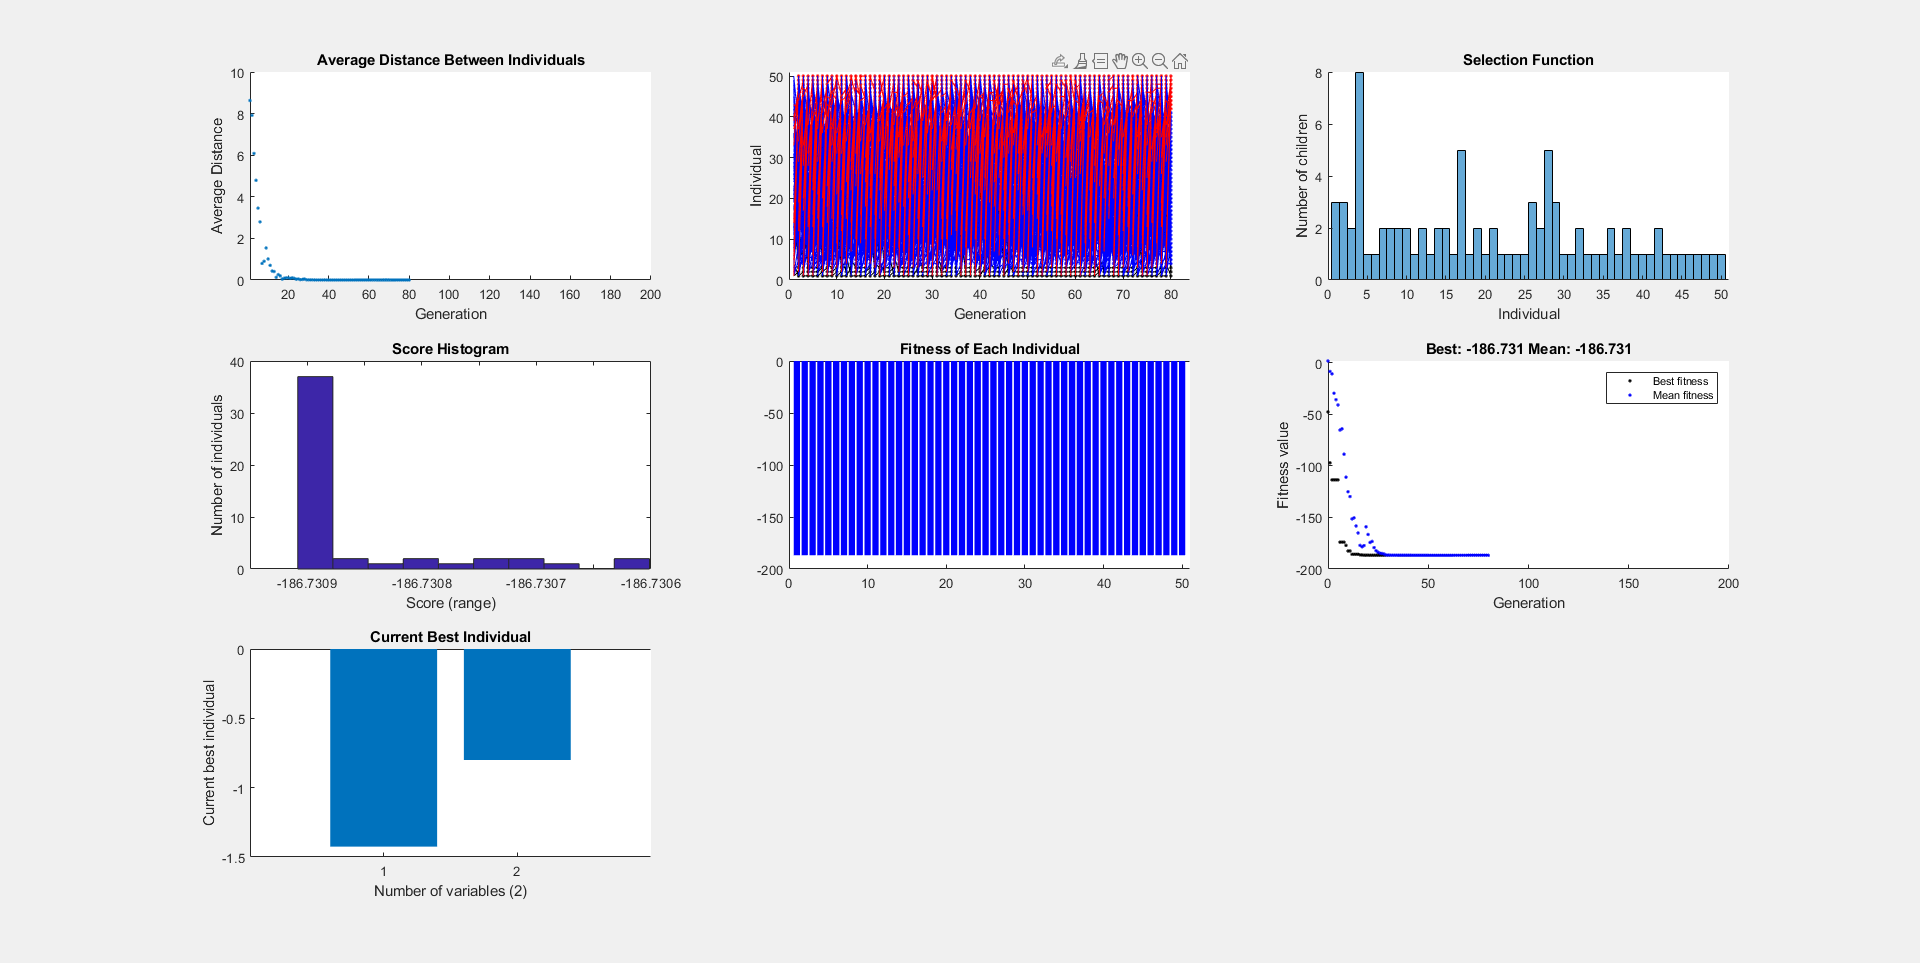

% Set nondefault solver options
options = optimoptions("ga","Display","iter","PlotFcn",["gaplotdistance",...
    "gaplotgenealogy","gaplotselection","gaplotscorediversity",...
    "gaplotscores","gaplotbestf","gaplotbestindiv"]);

% Solve
[solution,objectiveValue] = ga(fun,nvar,[],[],[],[],repmat(-10,nvar,1),...
    repmat(10,nvar,1),[],[],options);


% Clear variables
clearvars options

nvar = 2;
fun = @Shubert1_fun;
% Creation function 'gacreationlinearfeasible' and Mutation function
% 'mutationpositivebasis' gave best result so far, with -186.7304 at
% [-0.8008, 4.8581]. Global minima is -186.730909